clear
clc

station             = 'M1';

[fs, constant, AFR_freq, AFR] = get_station_parameters(station);

                            % ( year, month, day, hour, min, sec)
start_time          = datetime( 2014,     6,  20,    9,  40,   0);
end_time            = datetime( 2014,     6,  20,   10,  40,   0);
singe_file_duration = 600;  %sec
path                = 'D:\Bachelor degree\github\';

data_array = read_data(station, start_time, end_time, singe_file_duration, path);

adc_resolution      = 16;
V_max               = 0.83;

data_array_V = bits_to_V(data_array, adc_resolution, V_max);

window_size         = fs*0.25;
window              = hamming(window_size);
noverlap            = 0.5*window_size;
dt                  = 60;

[Pxx, t, f] = spectrogram_Welch(data_array_V, fs);

Pxx = apply_afr(AFR_freq, AFR, f, Pxx);

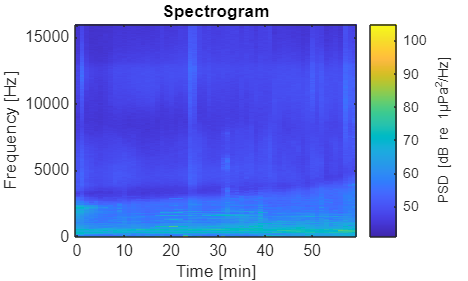

psd_plot(t, f, Pxx, constant)

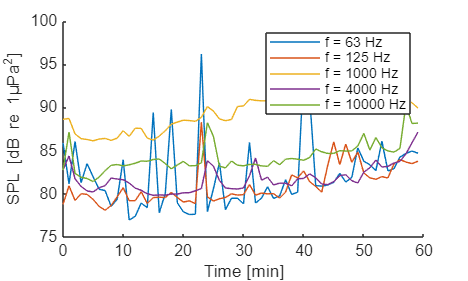

type = 'third_octave';
freq_array = [63, 125, 1000, 4000, 10000];

spl_plot(Pxx, t, f, constant, type, freq_array)